%some constants
sigma = 10;
r = 28;
b = 8/3;

## Butterfly effect (single oscilator)

N = 1; %number of nodes
x0 = randn(3*N,1)*0.1; %starting position
f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
] %system of equations

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N));r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


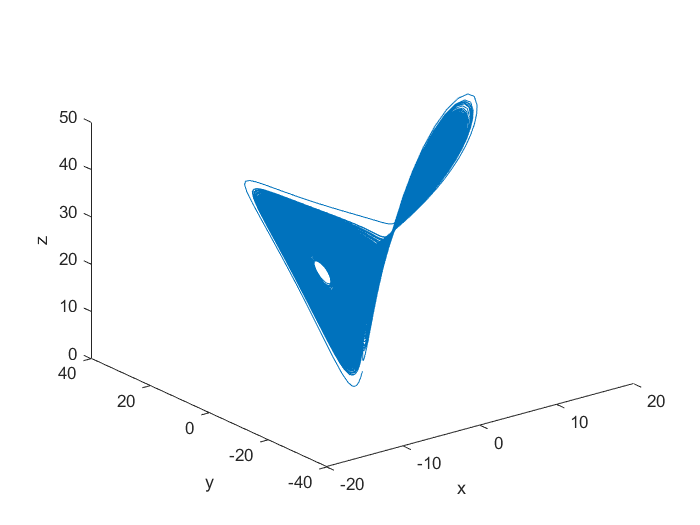

C = 0;
tspan = [0 2000]; %timespan
x0 = randn(3*N,1)*1e-1; %random starting positions
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0); %running the simulation

figure()
clf
plot3(X(:,1),X(:,2),X(:,3))
xlabel('x')
ylabel('y')
zlabel('z')

## Multiple oscilators

N = 4; %number of nodes
x0 = randn(3*N,1)*10;
f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N));r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


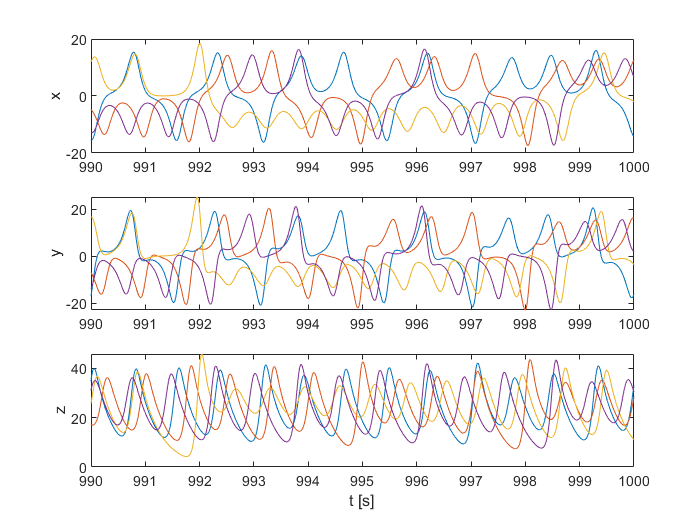

C = zeros(N,N);
tspan = [0 1000]; %time span over which to simulate
x0 = randn(3*N,1)*10; %setting random starting positions
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0);

plot3Ddata(N,T,X,false,10) %as can be seen no synchronization occurs

N = 6; %number of nodes

c_star = 10

c_star = 10

s = [1 2 3 3 4 5];
t = [2 3 4 5 6 6];

G = graph(s,t,[],N);
figure()
clf
%plot(G)
C = laplacian(G) * c_star;
full(C); %how to turn it into a full matrix
eig(C)

ans =    -0.0000
    4.3845
   20.0000
   20.0000
   30.0000
   45.6155


m = [ 0 0 0 1 0 0;
      0 0 0 1 -1 0;
];
m*C*pinv(m)

ans =    20.0000   -0.0000
   -0.0000   20.0000


f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


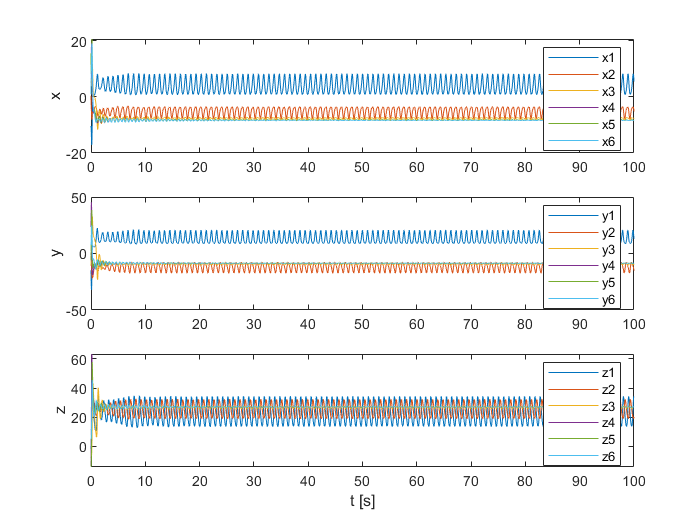

tspan = [0 100];
x0 = randn(3*N,1)*10;
[T, X] = ode23(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0,odeset('RelTol',1e-6,'AbsTol',1e-6));
plot3Ddata(N,T,X,true,100)



N = 6; %number of nodes
s = [1 3 3 4 5];
t = [2 4 5 6 6];
G = graph(s,t,[],N);
figure()
clf
%plot(G)
C = laplacian(G) * c_star;
full(C); %how to turn it into a full matrix

%creating the connectivity matrix D
G = graph(2,3,[],N);
D = laplacian(G) * c_star;

f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N) - D*x(N+1:2*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz   
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N)-D*x(N+1:2*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


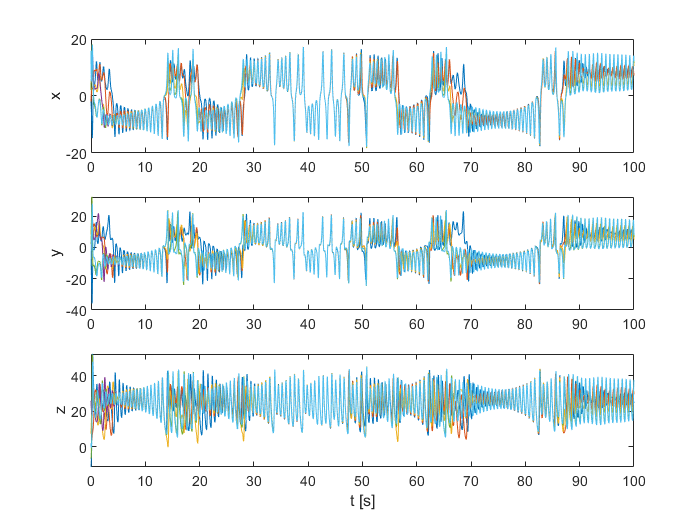

tspan = [0 100];
x0 = randn(3*N,1)*10;
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0);
plot3Ddata(N,T,X,false)

Six node circle

N = 6; %number of nodes

c_star = 8

c_star = 8

s = [1 2 3 4 5 6];
t = [2 3 4 5 6 1];
G = graph(s,t,[],N);
C = laplacian(G) * c_star;

%creating the connectivity matrix D
s = [];
t = [];
G = graph(s,t,[],N);
D = laplacian(G) * c_star

D =    All zero sparse: 6×6


f = @(t,x,N,sigma,r,b,C)[
    sigma*(x(N+1:2*N)-x(1:N)) - C*x(1:N); %dx
    r*x(1:N) - x(N+1:2*N) - x(1:N).*x(2*N+1:3*N) - D*x(N+1:2*N); %dy
    -b*x(2*N+1:3*N) + x(1:N).*x(N+1:2*N); %dz   
]

f = function_handle with value:
    @(t,x,N,sigma,r,b,C)[sigma*(x(N+1:2*N)-x(1:N))-C*x(1:N);r*x(1:N)-x(N+1:2*N)-x(1:N).*x(2*N+1:3*N)-D*x(N+1:2*N);-b*x(2*N+1:3*N)+x(1:N).*x(N+1:2*N)]


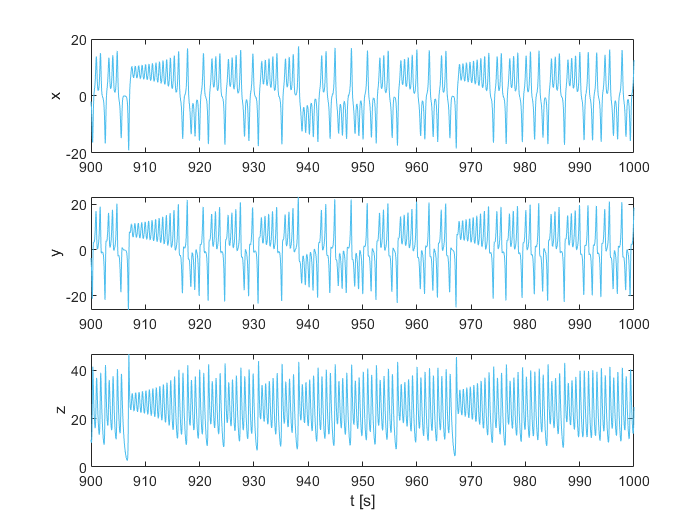

tspan = [0 1000];
x0 = randn(3*N,1)*10;
[T, X] = ode45(@(t,x)f(t,x,N,sigma,r,b,C),tspan,x0,odeset('RelTol',1e-6,'AbsTol',1e-6));

plot3Ddata(N,T,X,false,100)

N = 6; %number of nodes
sx = [1 2 3 4 5];
tx = [2 3 4 6 6];
Gx = graph(sx,tx,[],N);
C = laplacian(Gx) * c_star;
full(C); %how to turn it into a full matrix

%creating the connectivity matrix D
sy = [3];
ty = [5];
Gy = graph(sy,ty,[],N);
D = laplacian(Gy) * c_star;

dx = distances(Gx);
dx(dx == inf) = 0; %removing infinite distances because that is no paths
bx = sum(sum(dx))/2 %total distances without duplicates

bx = 35

dy = distances(Gy);
dy(dy == inf) = 0;
by = sum(sum(dy))/2

by = 1

G_int = addedge(Gx, sy, ty); %combining graphs  
d_int = distances(G_int);
d_int(d_int == 0) = 0;
b_int = sum(sum(d_int))/2 - bx - by%weet niet of dit klopt

b_int = -7